# **LPV-MPC Scheduling Trajectory Estimation: Methods Comparison**

This Live Script provides a side-by-side comparison of the four scheduling estimation methods available in CHRONOS: **Frozen**, **LPV-RTI (Warm-Start)**, **LPV-SQP (Iterative)**, and **Taylor Recursive**.  

We use the nonlinear **Furuta pendulum** benchmark to evaluate the trade-off between closed-loop tracking performance and computational burden.

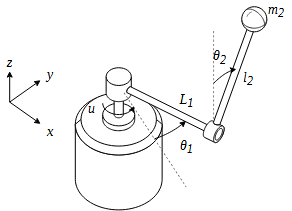

This plant is a challenging benchmark for control engineering, being an underactuated mechanical system with coupled, highly nonlinear, and fast dynamics.

To compare the different methods, the script runs the exact same scenario four times, resetting the plant and controller states before each run to ensure a fair comparison.

## Sequential Closed-Loop Simulation

To prevent the prediction errors of one method from corrupting the warm-start trajectory of the next, the simulations are run sequentially in independent loops. For each method, the ``two_tank_init`` script is called to cleanly reset the ``mpc`` structure and the initial states.

clear; clc; close all;

%% Simulation Setup & Method Configuration
tsim = 25; % seconds
Ts = 0.02; % 20 ms sampling time
Sim_samples = tsim / Ts;
time = 0:Ts:tsim-Ts;

methods_names = {'1. Frozen', '2. LPV-RTI', '3. LPV-SQP', '4. Taylor'};
num_methods = length(methods_names);
n_iter_sqp = 5; % Max inner iterations for LPV-SQP


Since qLPV_Furuta_SS takes the full state '$x
$', the scheduling parameter.

 $\rho$ is simply the state itself. Thus, the Jacobian is the Identity matrix!

n_rho = 4;
my_sched_fun = @(x) x;
my_jacob_fun = @(x) eye(4);

% Physical bounds for Taylor clipping (matching state constraints)
rho_min = [-3.1416; -100; -30; -30];
rho_max = [ 3.1416;  100;  30;  30];

%% Preallocate Storage Arrays
th1_all  = zeros(num_methods, Sim_samples);
th2_all  = zeros(num_methods, Sim_samples);
dth1_all = zeros(num_methods, Sim_samples);
dth2_all = zeros(num_methods, Sim_samples);
u_all    = zeros(num_methods, Sim_samples);
t_all    = zeros(num_methods, Sim_samples);
iter_all = zeros(num_methods, Sim_samples);
ref_dat  = zeros(1, Sim_samples); 


Run Sequential Simulations for Each Method

for m = 1:num_methods
    fprintf('Running Method %s...\n', methods_names{m});
    
    % Initialize MPC and plant state to downward resting position
    furuta_init; % Resets mpc, x = [0; pi; 0; 0], and u_prev = 0
    
    for i = 1:Sim_samples
        t_curr = time(i);
        
        % Step reference for arm angle theta1 at t = 11s
        if t_curr >= 11.0, th1_ref = pi/2; else, th1_ref = 0.0; end
        ref = [th1_ref; 0; 0; 0];
        if m == 1, ref_dat(i) = th1_ref; end % Store reference once
        
        % Disturbance impulse at t = 20s
        if t_curr >= 20.0 && t_curr < 20.1, d_u = 0.3; else, d_u = 0.0; end
        
        tic;
        
        %% Scheduling trajectory estimation
        if m == 1 % Frozen Approach
            Pk = compute_scheduling_frozen(mpc, x, my_sched_fun);
            
        elseif m == 2 % LPV-RTI (Warm-Start)
            % First sample doesn't have a valid previous prediction
            if i == 1, Pk = compute_scheduling_frozen(mpc, x, my_sched_fun);
            else, Pk = compute_scheduling_lpv_rti(mpc, x, my_sched_fun, n_rho); end
            
        elseif m == 3 % LPV-SQP (Iterative Refinement)
            % We needed to adapt the scheduling trajectory estimation for
            % taking into account the M matrix. Future updates would create
            % a new compute_scheduling_lpv_sqp function to handle that
            if i == 1
                Pk = compute_scheduling_frozen(mpc, x, my_sched_fun);
            else
                % Custom SQP Loop for Continuous API with Mass Matrix M
                Pk = compute_scheduling_lpv_rti(mpc, x, my_sched_fun, n_rho);
                mpc_tmp = mpc;
                for iter_sqp = 1:n_iter_sqp
                    Ac_lpv = project_matrix(@get_Ac, Pk, n_rho, mpc.N);
                    Mc_lpv = project_matrix(@get_Mc, Pk, n_rho, mpc.N);
                    mpc_tmp = update_mpc_dyn_continuous_forward(mpc_tmp, Ac_lpv, Bc, [], Ts, Mc_lpv);
                    
                    [~, mpc_tmp, ~] = mpc_solve(mpc_tmp, x, u_prev, ref, [], [], [], []);
                    
                    Pk_new = compute_scheduling_lpv_rti(mpc_tmp, x, my_sched_fun, n_rho);
                    if norm(Pk_new - Pk, inf) < 1e-4
                        Pk = Pk_new; break;
                    end
                    Pk = Pk_new;
                end
            end
            
        elseif m == 4 % Taylor Recursive
            if i == 1, Pk = compute_scheduling_frozen(mpc, x, my_sched_fun);
            else, Pk = compute_scheduling_taylor_recursive(mpc, x, n_rho, my_sched_fun, my_jacob_fun, rho_min, rho_max); end
        end
        
        %% Update dynamics and solve
        Ac_lpv = project_matrix(@get_Ac, Pk, n_rho, mpc.N);
        Mc_lpv = project_matrix(@get_Mc, Pk, n_rho, mpc.N);
        mpc = update_mpc_dyn_continuous_forward(mpc, Ac_lpv, Bc, [], Ts, Mc_lpv);
        
        [u_k, mpc, iter] = mpc_solve(mpc, x, u_prev, ref, [], [], [], []);
        tk = toc;
        
        %% Store data
        th1_all(m, i)  = x(1);
        th2_all(m, i)  = x(2);
        dth1_all(m, i) = x(3);
        dth2_all(m, i) = x(4);
        u_all(m, i)    = u_k;
        t_all(m, i)    = tk;
        iter_all(m, i) = iter;
        
        %% Integrate nonlinear plant (RK4)
        u_applied = u_k + d_u;
        k1 = Furuta(x, u_applied);
        k2 = Furuta(x + 0.5*Ts*k1, u_applied);
        k3 = Furuta(x + 0.5*Ts*k2, u_applied);
        k4 = Furuta(x + Ts*k3, u_applied);
        x = x + (Ts/6)*(k1 + 2*k2 + 2*k3 + k4);
        
        u_prev = u_k;
    end
end

Running Method 1. Frozen...
Running Method 2. LPV-RTI...
Running Method 3. LPV-SQP...
Running Method 4. Taylor...


# **Evaluating the scheduling methods**

Now, we use quantitative metrics and visual results for evaluating the distinct scheduling trajectory methods.

## Metrics

We compute the Root Mean Square Error (RMSE) and the RMS of the Associate Cost (RMS-J), as well as the average and maximal computing time and the average number of iterations for solving the QP:

%% Calculate Metrics and Display Quantitative Table
Metrics = zeros(num_methods, 6); % [RMS Th1, RMS Th2, RMS Cost, Avg Time, Max Time, Avg Iters]

for m = 1:num_methods
    % RMS Error ignores the first 6 seconds (swing-up transient) for fair tracking evaluation
    eval_idx = time > 6.0; 
    
    % State error and control effort
    err_th1  = th1_all(m, eval_idx) - ref_dat(eval_idx);
    err_th2  = th2_all(m, eval_idx) - 0;
    err_dth1 = dth1_all(m, eval_idx) - 0;
    err_dth2 = dth2_all(m, eval_idx) - 0;
    u_eval   = u_all(m, eval_idx);
    
    % Real associate cost: J_stage = x'Qx + u'Ru 
    % (Weights from furuta_init.m: Q = diag([10, 100, 5, 1]), R = 100)
    J_stage = 10*(err_th1.^2) + 100*(err_th2.^2) + 5*(err_dth1.^2) + 1*(err_dth2.^2) + 100*(u_eval.^2);
    
    Metrics(m, 1) = sqrt(mean(err_th1.^2));            % RMS Theta 1
    Metrics(m, 2) = sqrt(mean(err_th2.^2));            % RMS Theta 2
    Metrics(m, 3) = sqrt(mean(J_stage.^2));            % RMS Cost (J_reg)
    Metrics(m, 4) = mean(t_all(m, :)) * 1000;          % Avg CPU Time (ms)
    Metrics(m, 5) = max(t_all(m, :)) * 1000;           % Max CPU Time (ms)
    Metrics(m, 6) = mean(iter_all(m, :));              % Avg Iterations
end

% Extract the best (minimum) values to highlight later
best_vals = min(Metrics, [], 1);

% Create a Table
VariableNames = {'RMS_Th1_rad', 'RMS_Th2_rad', 'RMS Cost', 'Avg_Time_ms', 'Max_Time_ms', 'Avg_Iters'};
RowNames = methods_names;

ResultsTable = array2table(Metrics, 'RowNames', RowNames, 'VariableNames', VariableNames);

% Display the table cleanly
disp(ResultsTable);

                  RMS_Th1_rad    RMS_Th2_rad    RMS Cost    Avg_Time_ms    Max_Time_ms    Avg_Iters
                  ___________    ___________    ________    ___________    ___________    _________

    1. Frozen       0.29178        0.01647       6.5811       14.663         130.01        1.5968  
    2. LPV-RTI      0.29159       0.016462       6.5661       14.825         70.725        1.6296  
    3. LPV-SQP       0.2914       0.016462       6.5494       37.108         212.26        1.5712  
    4. Taylor       0.29152       0.016554       6.5757       15.259         89.264        1.6416  



The quantitative metrics presented in the table align perfectly with the theoretical expectations regarding the trade-off between prediction accuracy and computational burden for qLPV NMPC formulations.  

The** LPV-SQP (Iterative)** approach yields the lowest tracking errors (RMS $\theta_1
$, RMS $\theta_2
$) and the best overall controller performance (lowest RMS Cost). However, this high precision is achieved at a significant computational expense.

On the other hand, the **Frozen **approach presents the lowest average execution time, but results in the highest tracking errors and largest overall RMS cost, demonstrating its limitations when dealing with the highly nonlinear and fast dynamics of the Furuta pendulum swing-up. 

The results clearly highlight the **LPV-RTI (Warm-Start) **and **Taylor Recursive** methods as effective solutions for real-time control, achieving a good trade-off between control performance and computational cost. Both methods drastically reduce the maximum computational time compared to the SQP, while delivering tracking performance and RMS costs that are extremely close to the optimal iterative approach. 

## Results: Control Performance

The previous results are corroborated by the plot below, which compares the reference tracking and the generated control actions (inlet flow) qualitatively. 

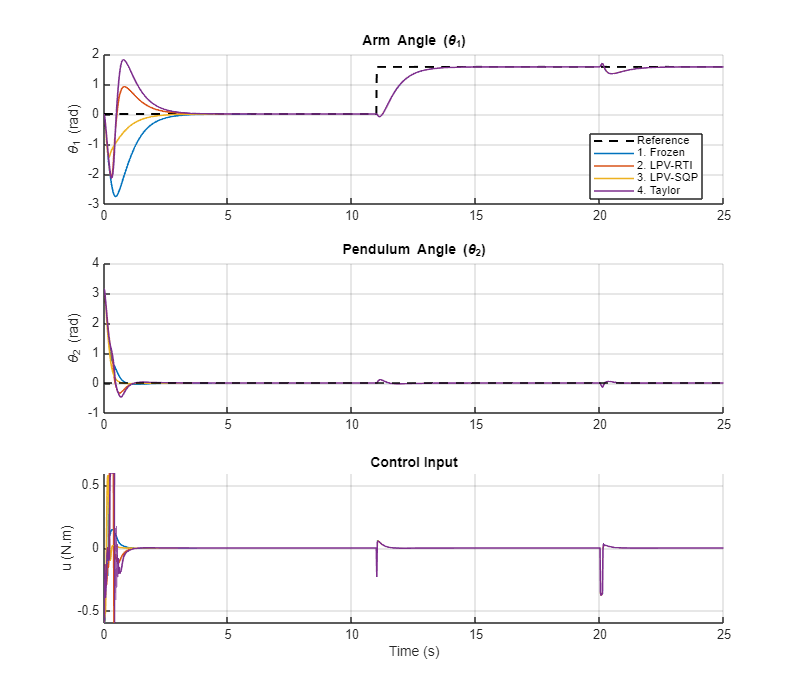

%% Plot Comparison: Control Performance
colors = lines(4);
figure('Name', 'Furuta Pendulum Control', 'Position', [100, 100, 800, 700]);

ax1 = subplot(3,1,1); hold on; grid on;
plot(time, ref_dat, '--k', 'LineWidth', 1.5, 'DisplayName', 'Reference');
for m = 1:num_methods, plot(time, th1_all(m, :), 'Color', colors(m,:), 'LineWidth', 1.2, 'DisplayName', methods_names{m}); end
ylabel('\theta_1 (rad)'); title('Arm Angle (\theta_1)'); legend('Location', 'best');

ax2 = subplot(3,1,2); hold on; grid on;
yline(0, '--k', 'LineWidth', 1.5, 'DisplayName', 'Upright Equilibrium');
for m = 1:num_methods, plot(time, th2_all(m, :), 'Color', colors(m,:), 'LineWidth', 1.2, 'DisplayName', methods_names{m}); end
ylabel('\theta_2 (rad)'); title('Pendulum Angle (\theta_2)');

ax3 = subplot(3,1,3); hold on; grid on;
for m = 1:num_methods, plot(time, u_all(m, :), 'Color', colors(m,:), 'LineWidth', 1.2, 'DisplayName', methods_names{m}); end
ylabel('u (N.m)'); xlabel('Time (s)'); title('Control Input');
linkaxes([ax1, ax2, ax3], 'x');

## Results: Computational Burden

High accuracy comes at a computational cost. The graphs below display the execution time per sample (in a logarithmic scale) and the number of inner Newton iterations required by the primal barrier solver.

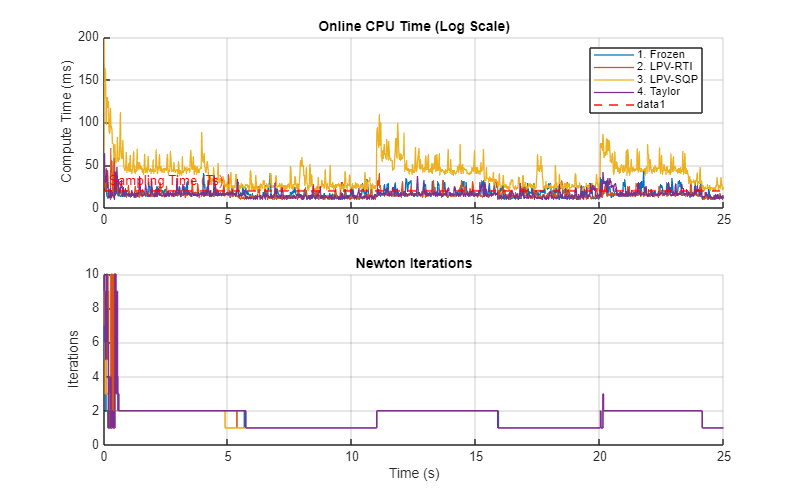

%% Plot Comparison: Computational Burden
figure('Name', 'Computational Burden', 'Position', [150, 150, 800, 500]);
subplot(2,1,1); hold on; grid on;
for m = 1:num_methods, semilogy(time, t_all(m, :) * 1000, 'Color', colors(m,:), 'LineWidth', 1.0, 'DisplayName', methods_names{m}); end
yline(Ts * 1000, '--r', 'Sampling Time (Ts)', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left');
ylabel('Compute Time (ms)'); title('Online CPU Time (Log Scale)'); legend('Location', 'best');

subplot(2,1,2); hold on; grid on;
for m = 1:num_methods, stairs(time, iter_all(m, :), 'Color', colors(m,:), 'LineWidth', 1.2, 'DisplayName', methods_names{m}); end
ylabel('Iterations'); xlabel('Time (s)'); title('Newton Iterations');